# Calculo de Z 

v0 y z0

 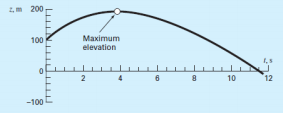

syms z(t) v(t) g c m z0 v0
eqnz = diff(z,t,2) + (c/m)*diff(z,t,1) == -g

$$eqnz(t) = \frac{\partial^{2}}{\partial t^{2}}z\left(t\right)+\frac{c\,\frac{\partial }{\partial t}z\left(t\right)}{m}=-g$$

zG = dsolve(eqnz)

$$zG = C_{3}+C_{4}\,{\mathrm{e}}^{-\frac{c\,t}{m}}-\frac{g\,m\,t}{c}$$

cond1 = z(0) == z0

$$cond1 = z\left(0\right)=z_{0}$$

Dz = diff(z,t,1)

$$Dz(t) = \frac{\partial }{\partial t}z\left(t\right)$$

cond2 = Dz(0) ==v0

$$cond2 = \left({\left(\frac{\partial }{\partial t}z\left(t\right)\right)|}_{t=0}\right)=v_{0}$$

condZ = [cond1 cond2]

$$condZ = \left(\begin{array}{cc} z\left(0\right)=z_{0} & \left({\left(\frac{\partial }{\partial t}z\left(t\right)\right)|}_{t=0}\right)=v_{0} \end{array}\right)$$

zP = dsolve(eqnz,condZ)

$$zP = \frac{z_{0}\,c^{2}+v_{0}\,c\,m+g\,m^{2}}{c^{2}}-\frac{{\mathrm{e}}^{-\frac{c\,t}{m}}\,\left(g\,m^{2}+c\,v_{0}\,m\right)}{c^{2}}-\frac{g\,m\,t}{c}$$